### load dataset - simple contrast (dummy coding) stim Cognitive

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel'

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel'

con_list = dir(fullfile(mount_dir, '*/con_0026.nii'));
spm('Defaults','fMRI')
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 24360228 bytes
Loading image number:    61
Elapsed time is 224.135738 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5943010  Bit rate: 22.50 bits


### `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              20:27:49 - 26/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


drawnow; snapnow

### run robfit

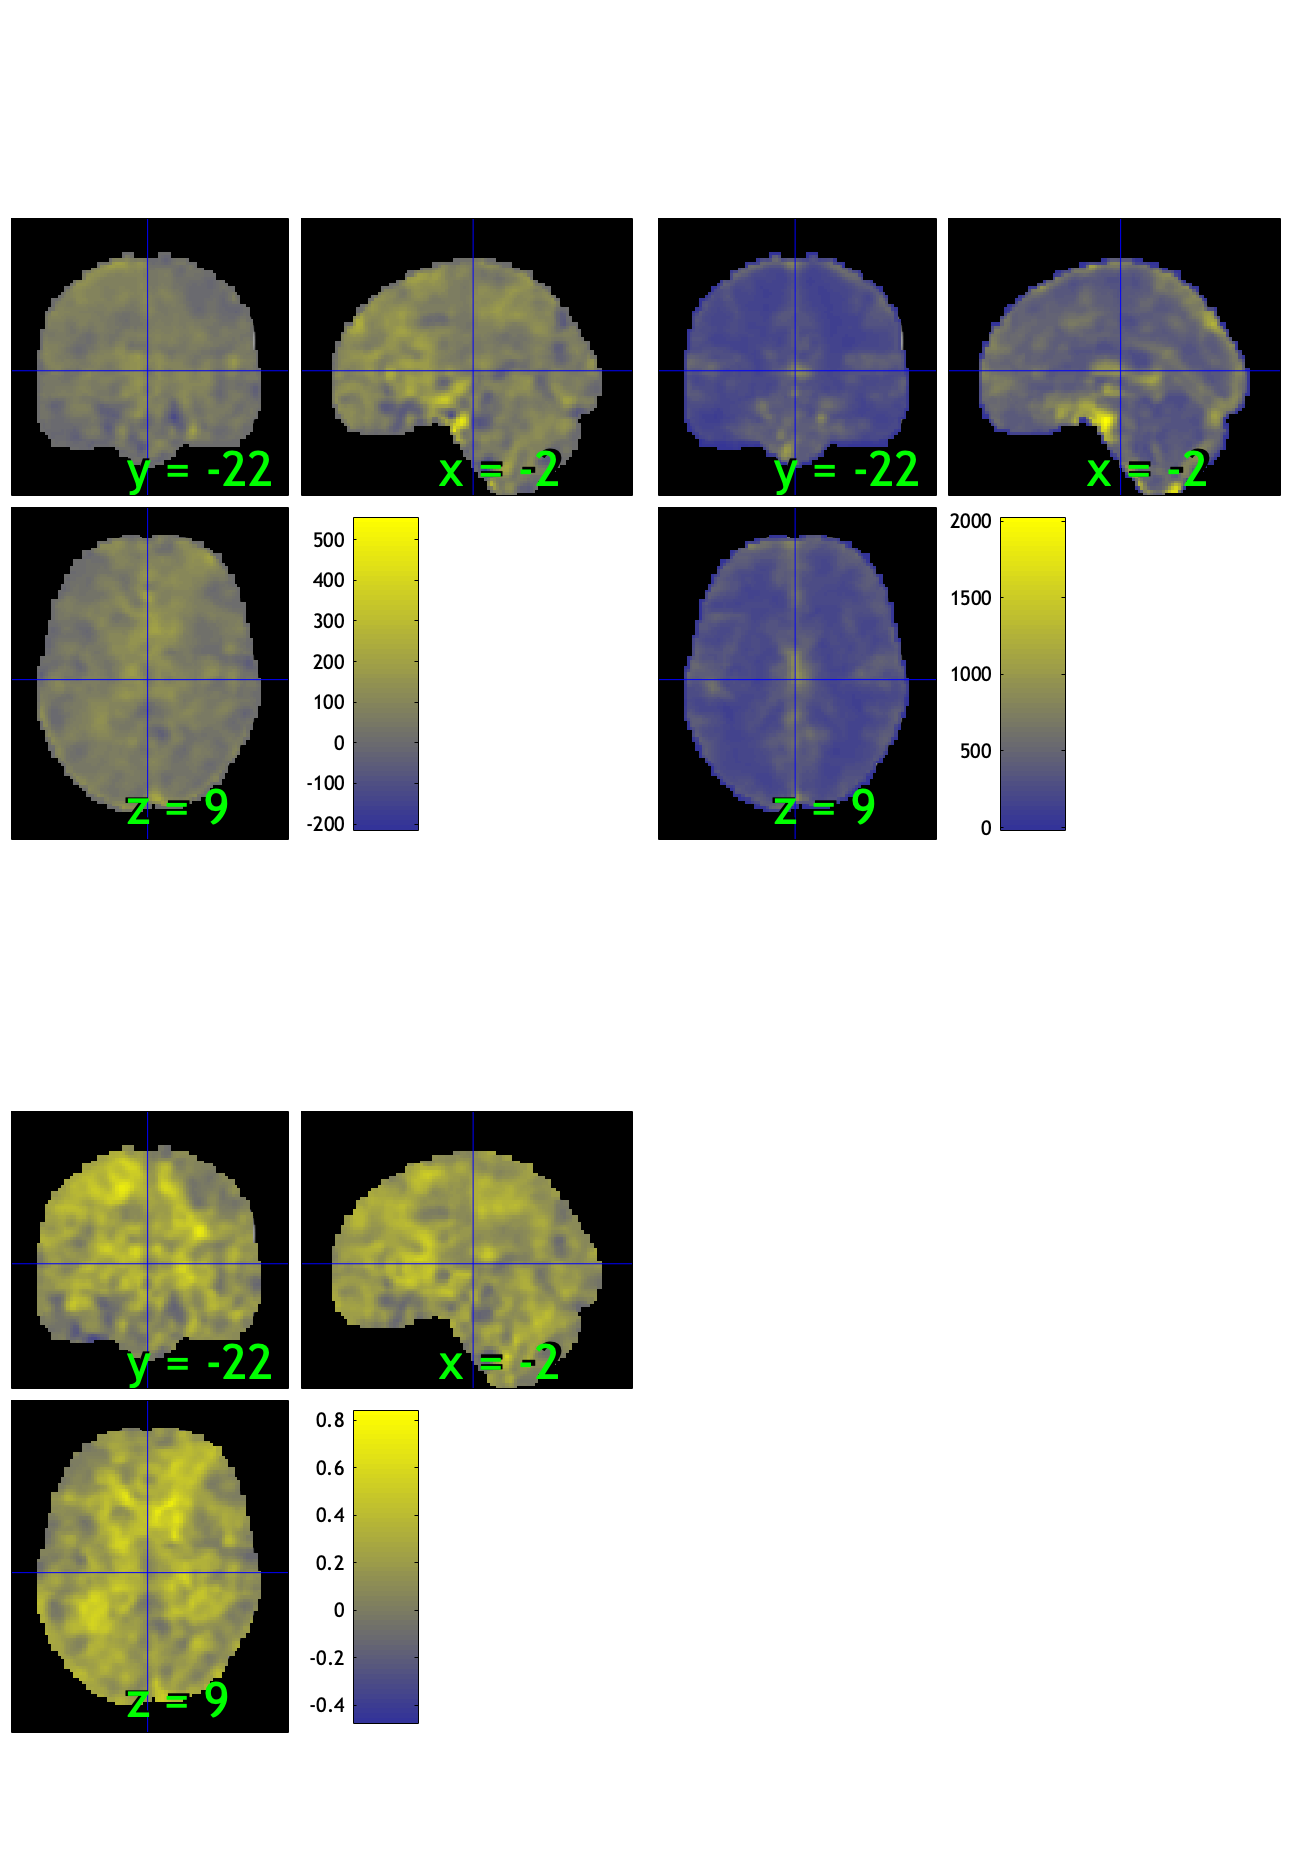

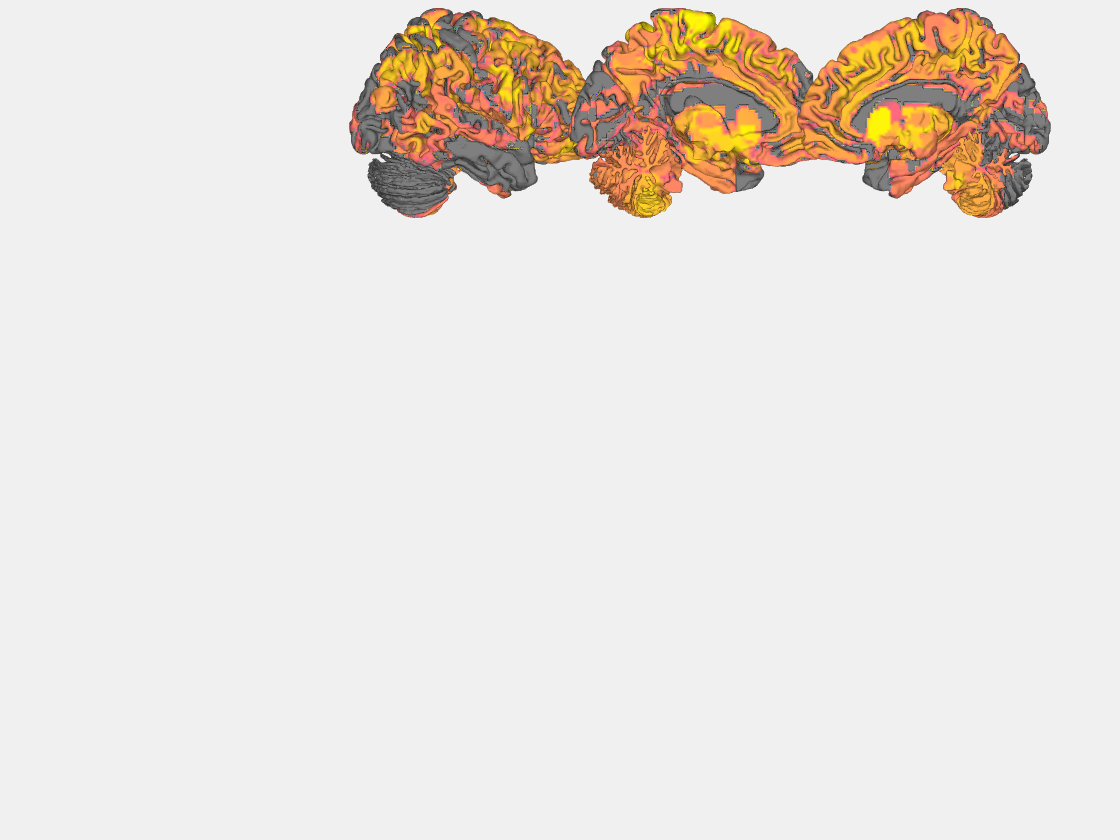

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat
Initializing nodes to match regions.
Updating node response data.
Updating obj.connectivity.nodes.
Updating obj.connectivity.nodes.
Updating region averages.
Updating obj.connectivity.regions.
Updating obj.connectivity.regions.
__________________________________________________________________
Input image diagnostic information
__________________________________________________________________
Retained 8 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 57.38%
Expected 3.05 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 31.15%
Expected 3.05 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 44 
Uncorrected:

    48



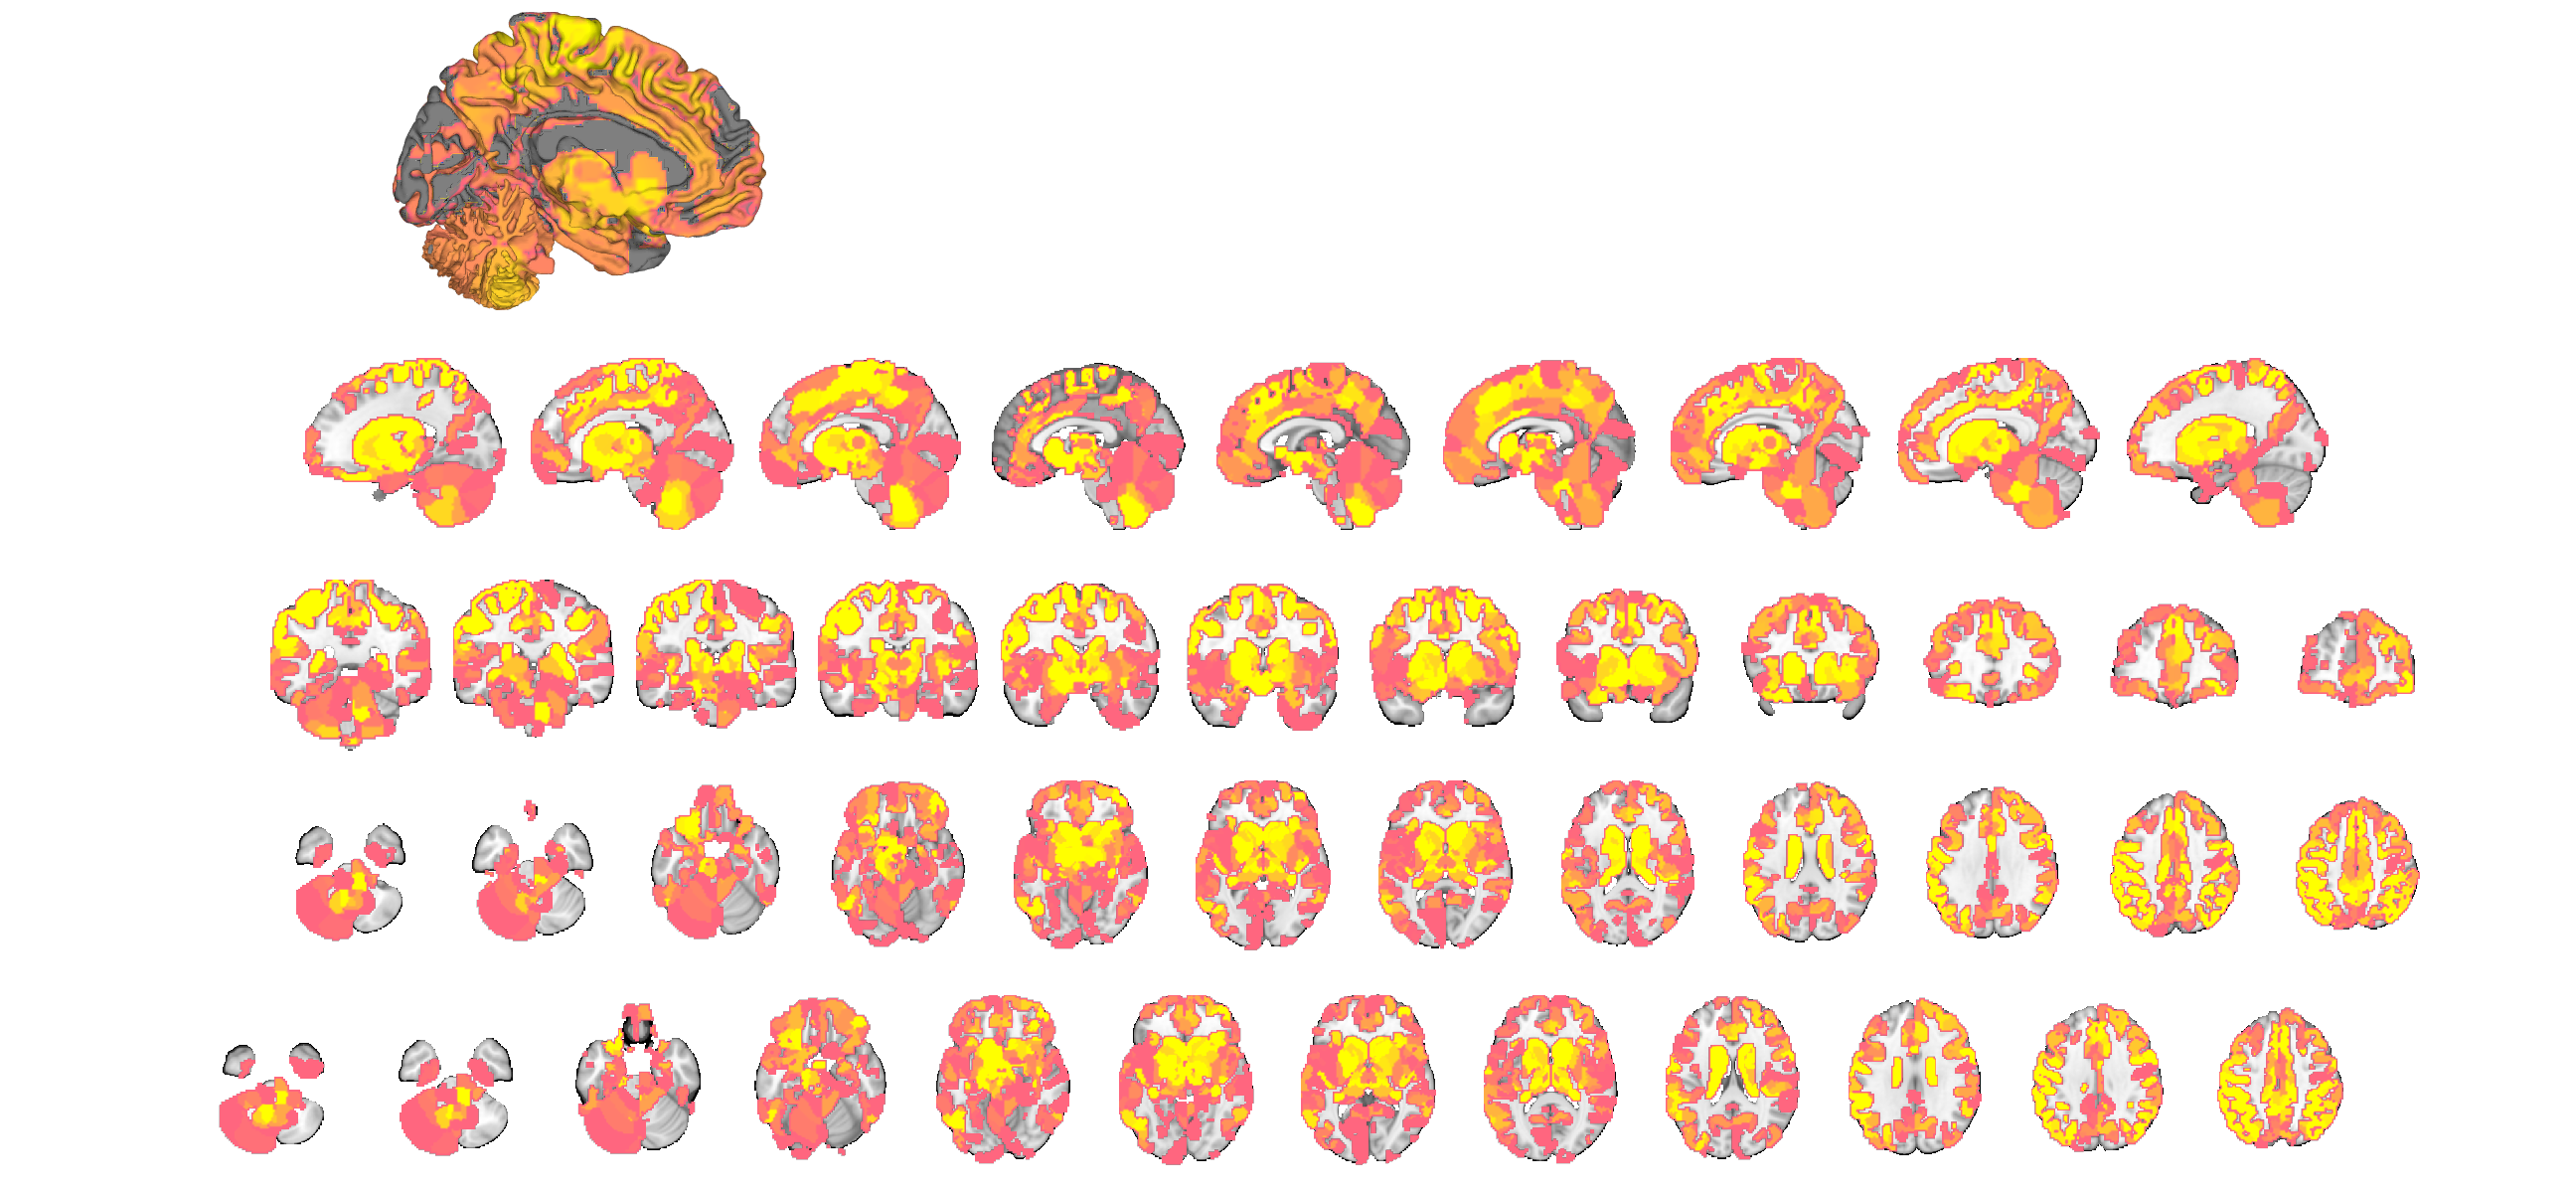

____________________________________________________________________________________________________________________________________________
Positive Effects
           Region             Volume            XYZ            maxZ       modal_label_descriptions      Perc_covered_by_label    Atlas_regions_covered    region_index
    ____________________    __________    ________________    ______    ____________________________    _____________________    _____________________    ____________

    {'Multiple regions'}    1.0582e+06    -6    -18     14    4.5373    {'Cerebellum'              }               3                      390                  1      
    {'Ctx_STSva_R'     }             8    54      0    -28    1.2225

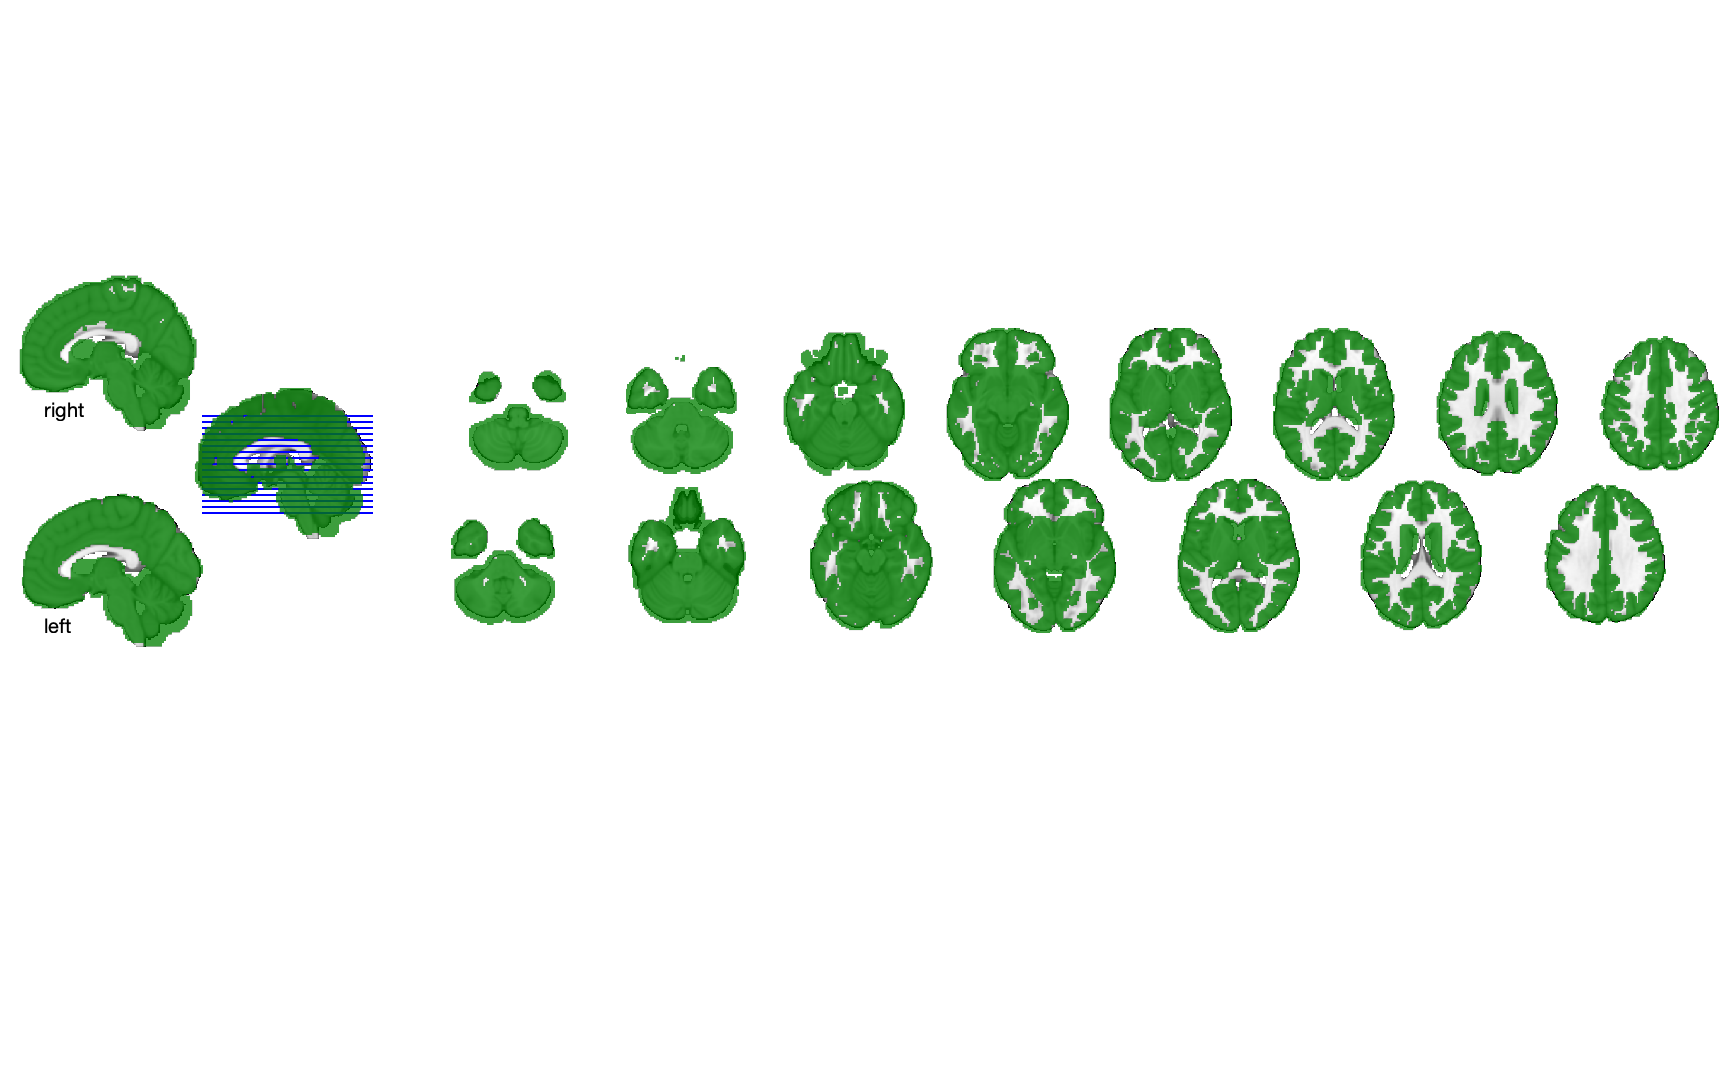

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 31.15%
Expected 3.05 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 44 
Uncorrected: 5 images		Cases 7 44 50 53 57 

Retained 8 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 57.38%
Expected 3.05 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
                               ________

SPM12: spm_check_registration (v7759)              20:30:51 - 26/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

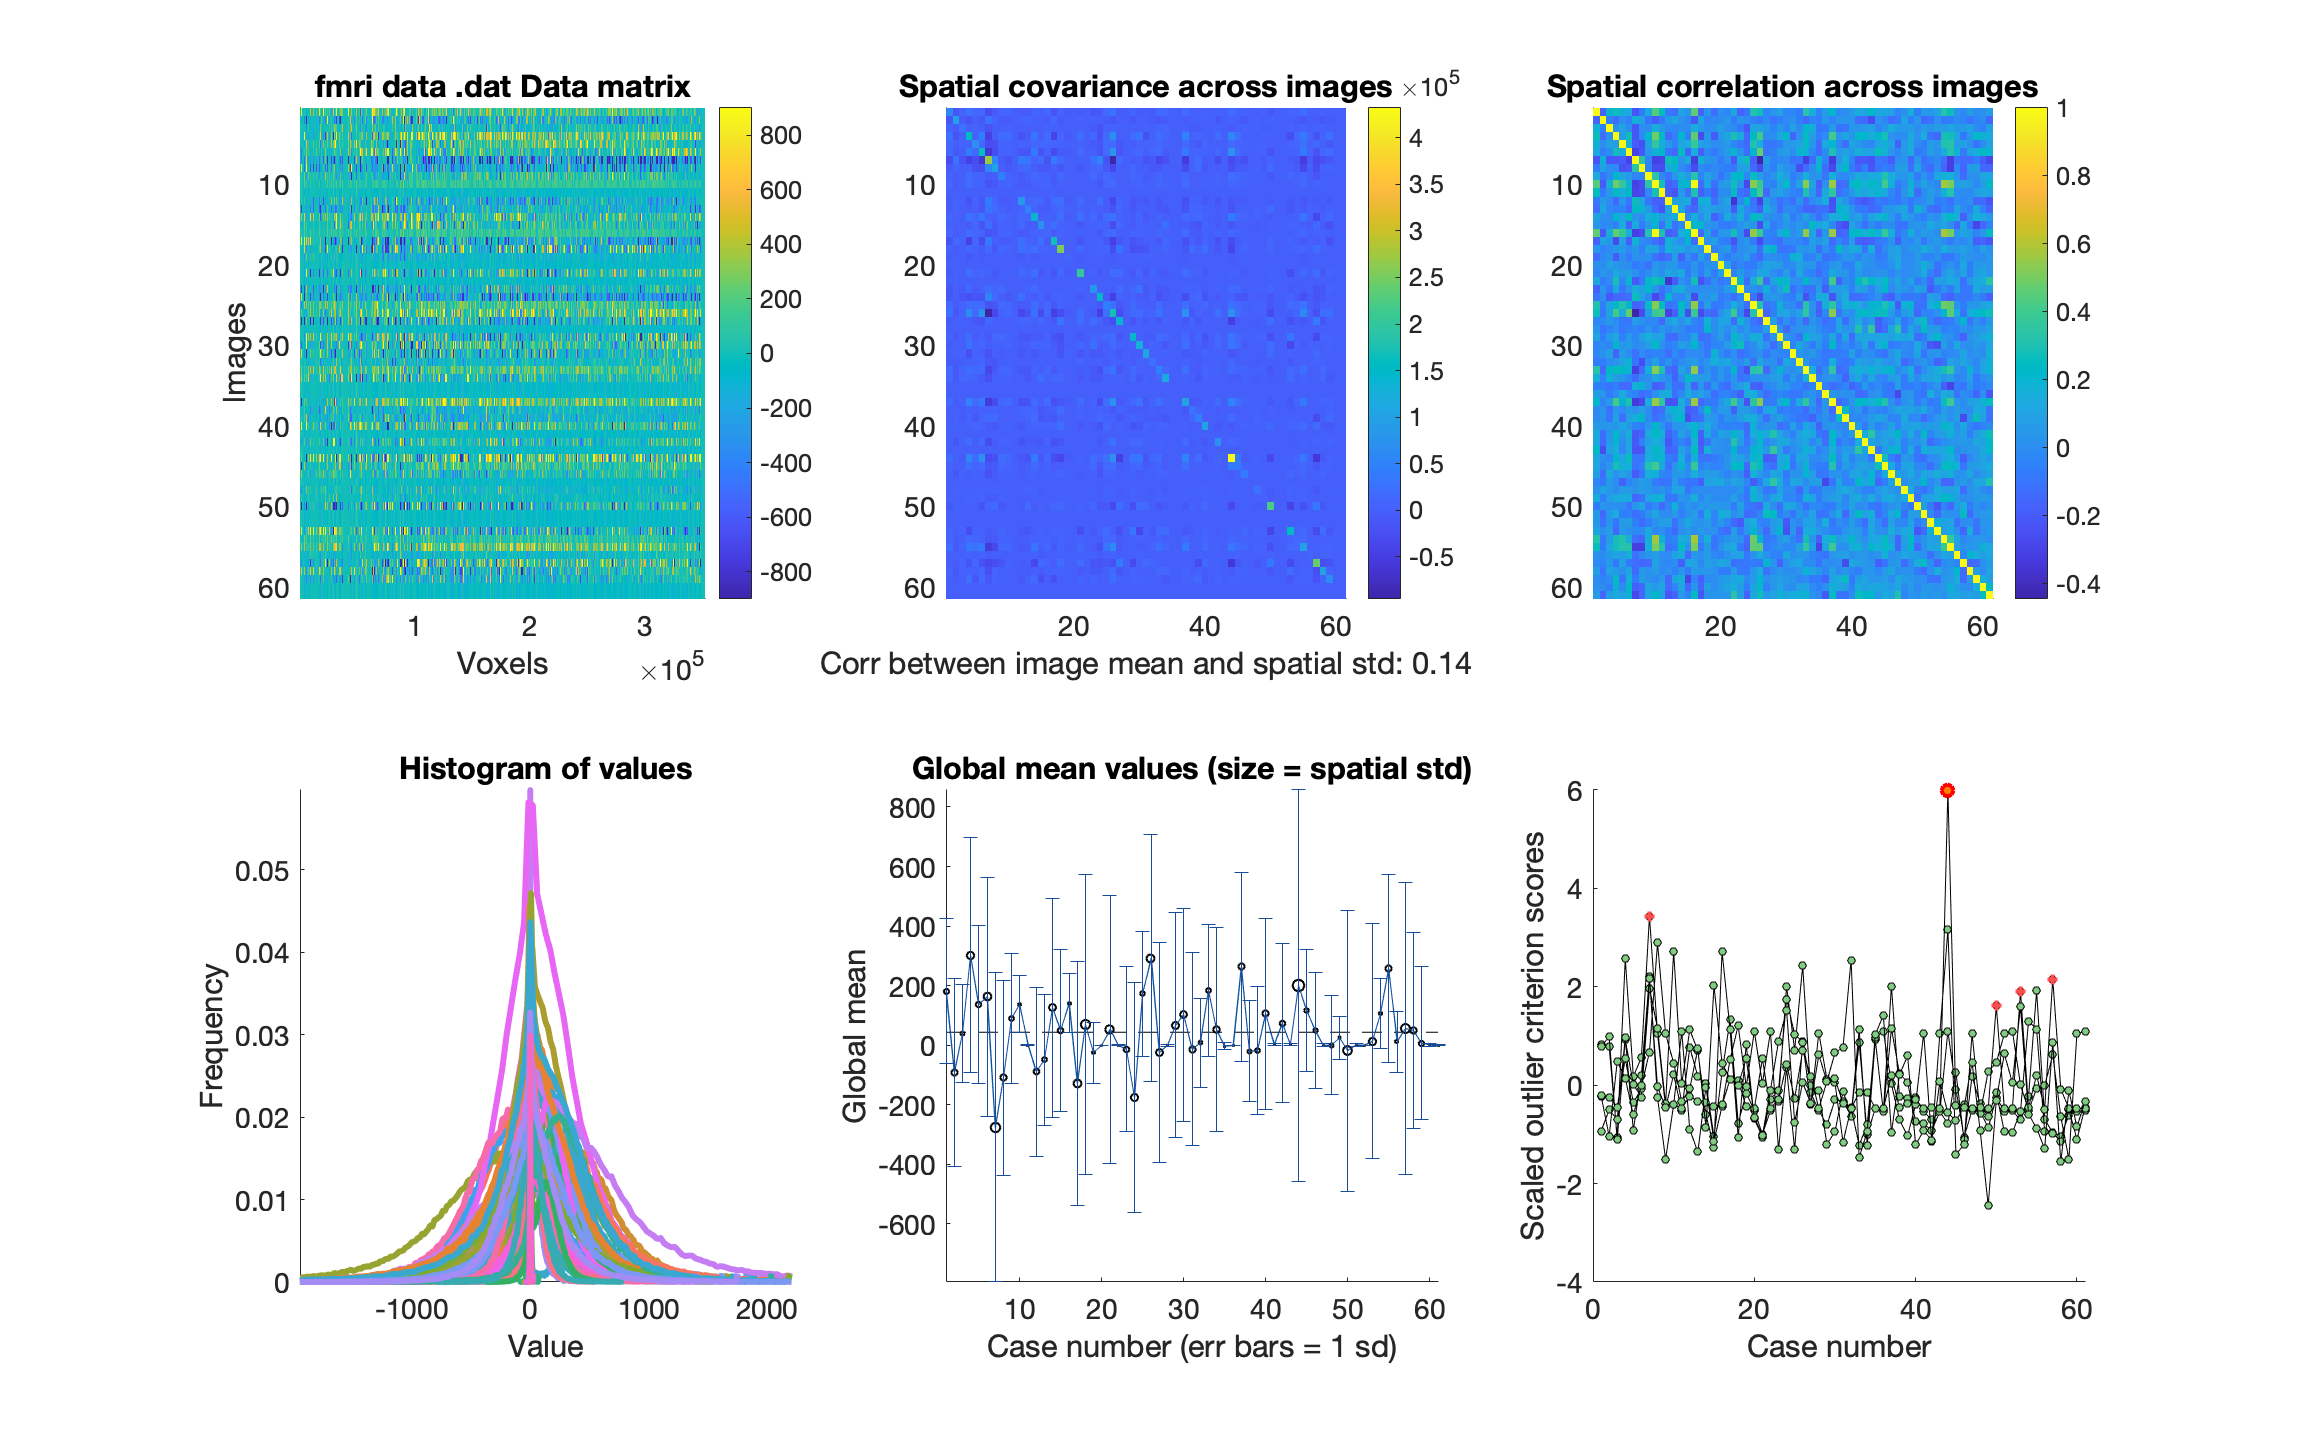

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


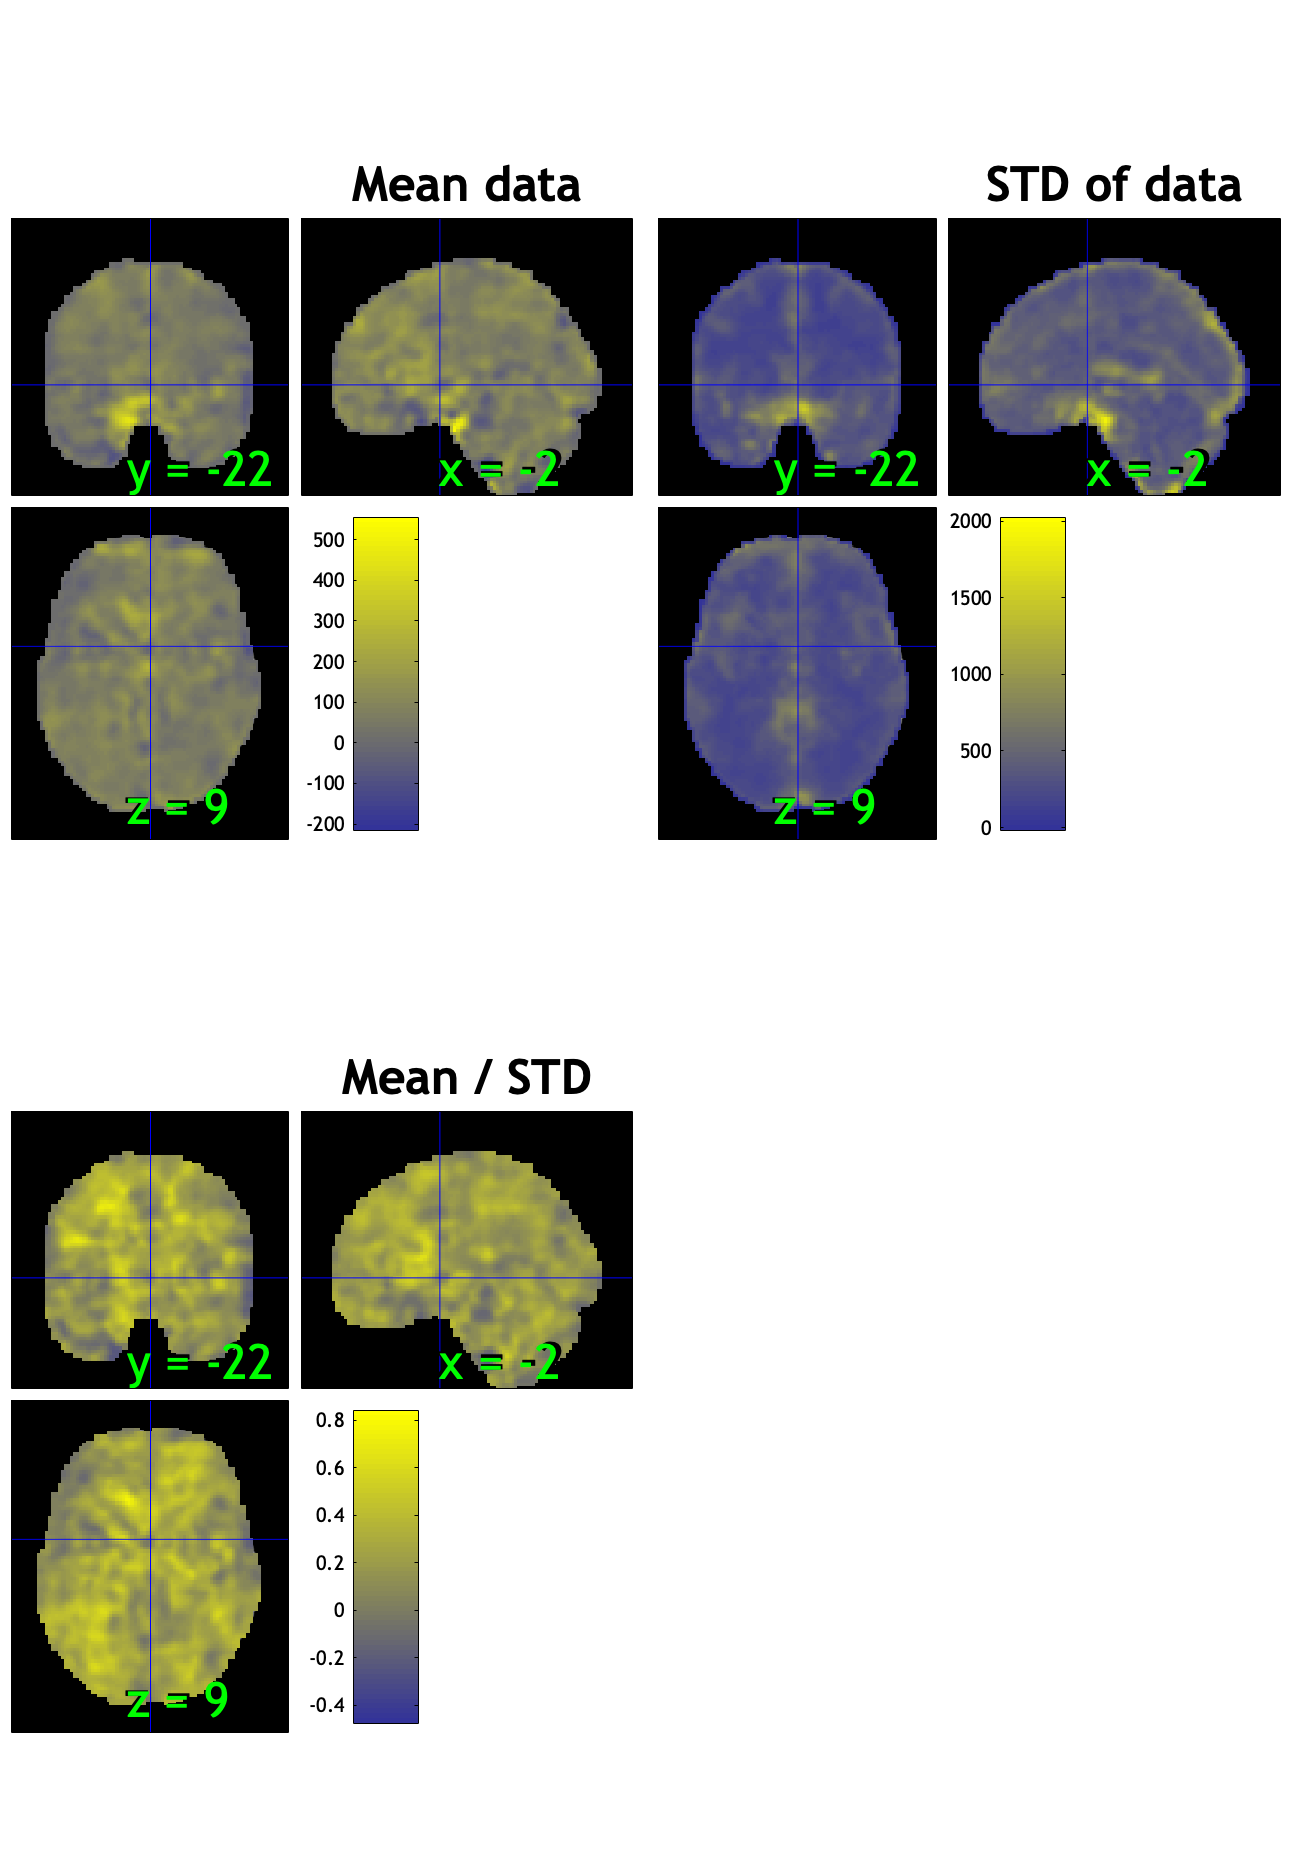

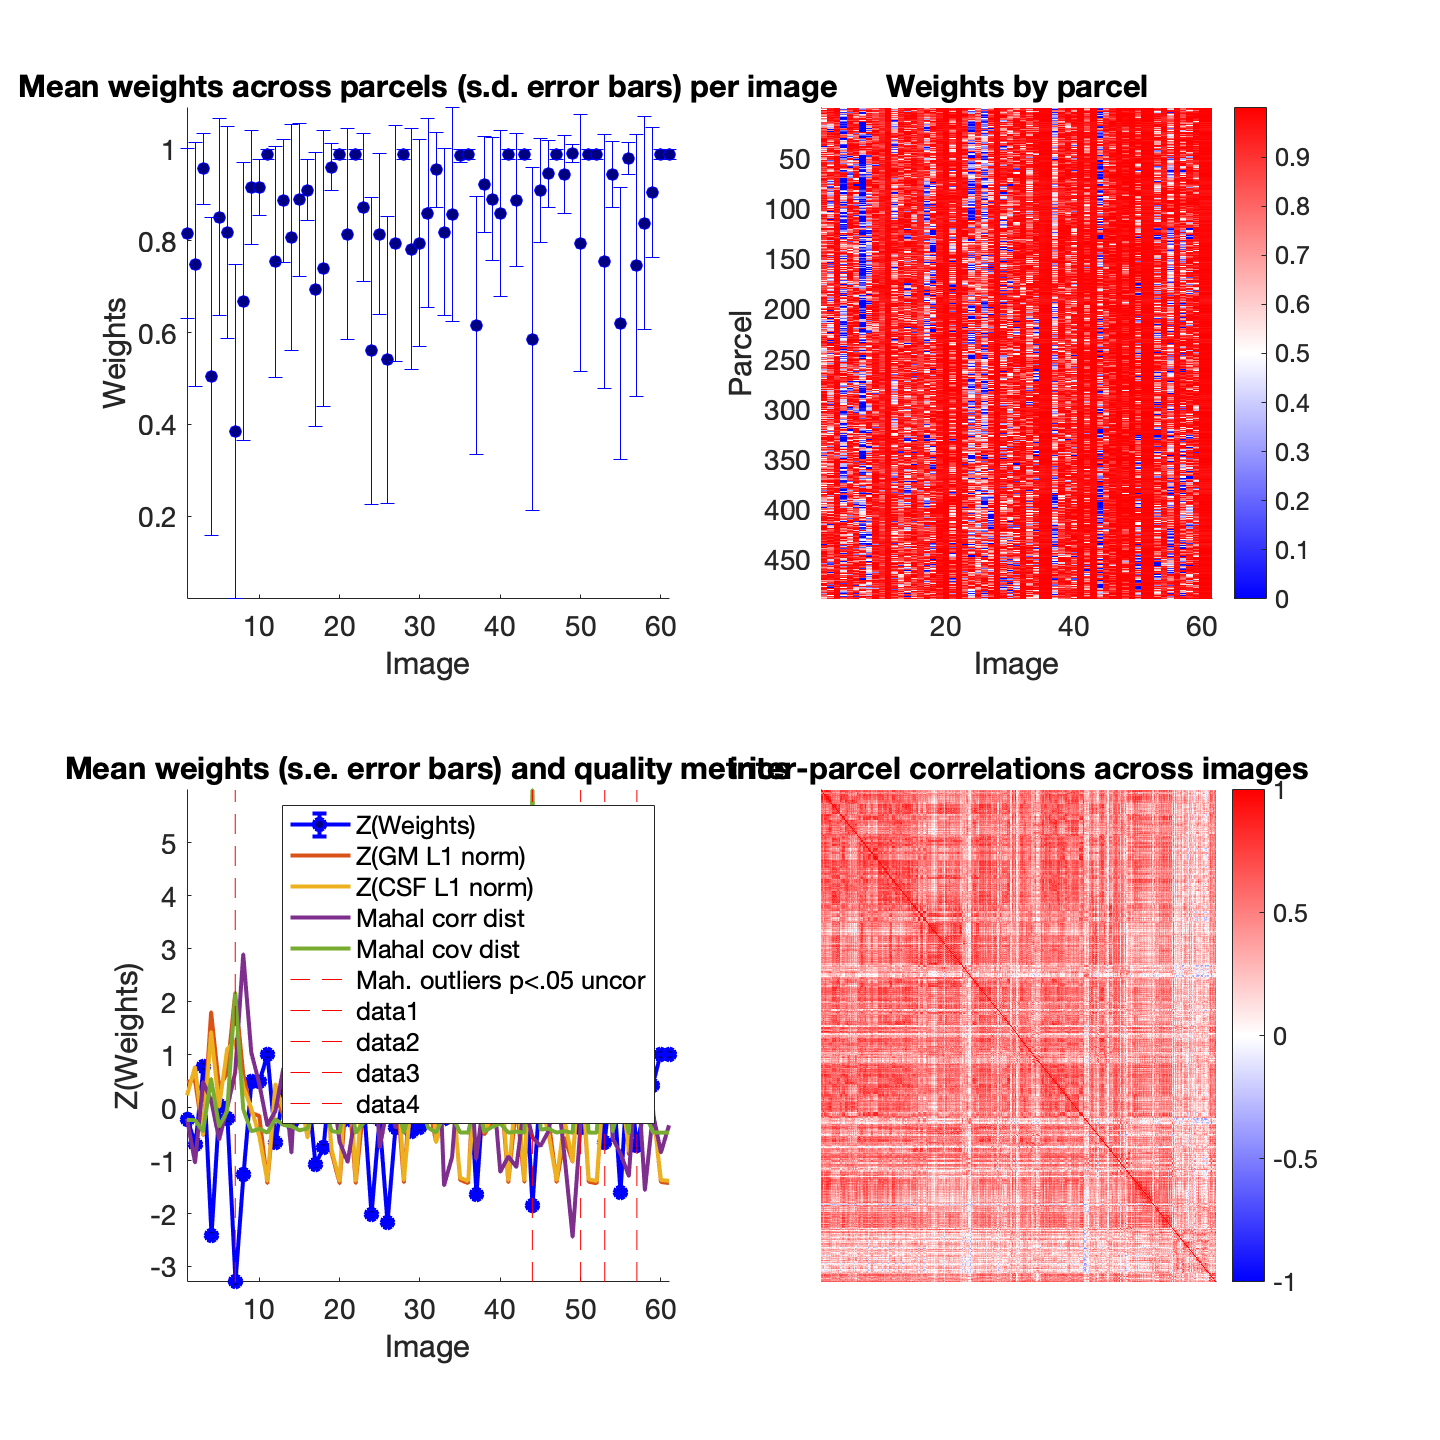

set(gcf,'Visible','on')
figure ('Visible', 'on');
out = robfit_parcelwise(con_data_obj);